# Trends of possible data patterns, parameters, relationships between data in the kaggle data set.

## Extracting data from the table

wpmain = readtable("water_pollution_disease.csv",ReadVariableNames=true);

### Separating data for  years into different tables

wp_2023 = wpmain(wpmain.Year == 2023, :);
wp_2024 = wpmain(wpmain.Year == 2024, :);

### Summarizing data by Year and Including mean Diarrheal Cases

YearSummary = groupsummary(wpmain,"Year","mean","DiarrhealCasesPer100_000People");

## LINE GRAPH YEARS BY DIARRHEAL CASES

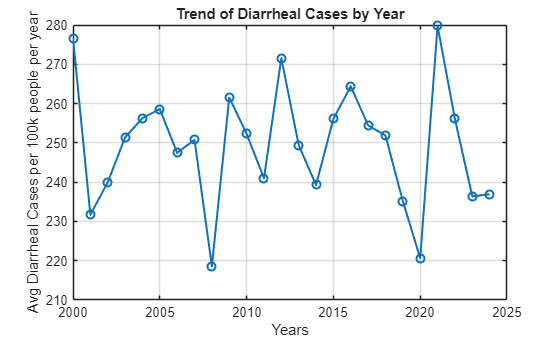

plot(YearSummary.Year, YearSummary.mean_DiarrhealCasesPer100_000People,'-o',LineWidth = 1.5)
xlabel("Years"); ylabel("Avg Diarrheal Cases per 100k people per year")
title("Trend of Diarrheal Cases by Year")
grid on
saveas(gcf,'Trend of Diarrheal Cases line graph.png')

## BAR CHART SHOWING  POPULATION DISTRIBUTION BY COUNTRY

### Summarizing data by countries and including Mean Information

C_summary = groupsummary(wpmain,"Country","mean",["PopulationDensity_peoplePerKm__","UrbanizationRate___","SanitationCoverage__OfPopulation_","DiarrhealCasesPer100_000People"]);

### Plotting the graph

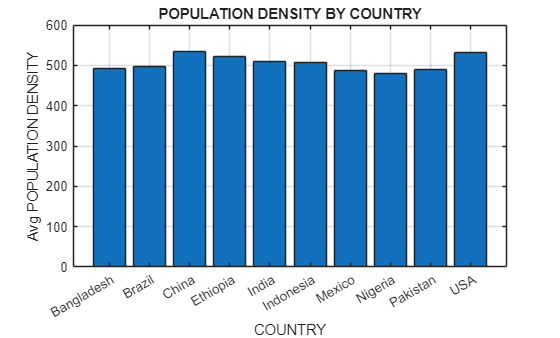

bar(categories(categorical(C_summary.Country)),C_summary.mean_PopulationDensity_peoplePerKm__)
xlabel("COUNTRY"); ylabel("Avg POPULATION DENSITY")
title("POPULATION DENSITY BY COUNTRY")
grid on
saveas(gcf,'POPULATION DENSITY BY COUNTRY BAR GRAPH.png')

## Scatter Relationship between Contaminant Level & CHOLERA Cases

### Summarizing data by Region and Year while Including Mean Information

regionYearSummary = groupsummary(wpmain,["Region","Year"],"mean",["CholeraCasesPer100_000People","ContaminantLevel_ppm_","BacteriaCount_CFU_mL_","DiarrhealCasesPer100_000People"]);

### Scatter Plot

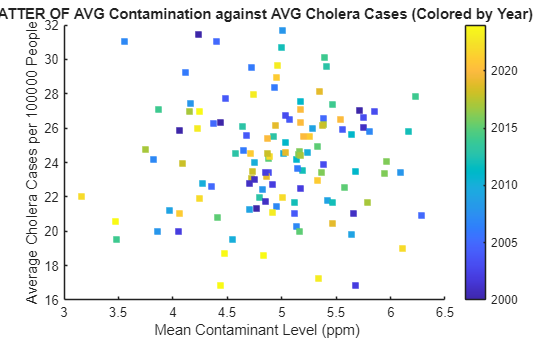

CO = regionYearSummary.mean_ContaminantLevel_ppm_;
CH = regionYearSummary.mean_CholeraCasesPer100_000People;
scatter(CO,CH,40,regionYearSummary.Year,"s","filled")
colorbar
xlabel(" Mean Contaminant Level (ppm)")
ylabel("Average Cholera Cases per 100000 People")
title("SCATTER OF AVG Contamination against AVG Cholera Cases (Colored by Year)")
saveas(gcf,'Contamination_Cholera Cases_ SCATTER PLOT.png')

## Distribution of Contaminant Levels

### Histogram plot 1

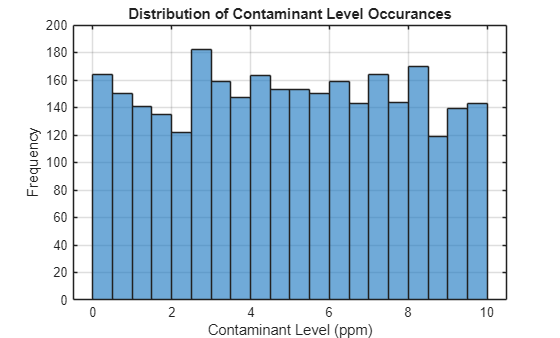

histogram(wpmain.ContaminantLevel_ppm_)
xlabel("Contaminant Level (ppm)")
ylabel("Frequency")
title("Distribution of Contaminant Level Occurances")
grid on
saveas(gcf,'Distribution of Contaminant Level HISTOGRAM.png')

### Histogram Plot 2

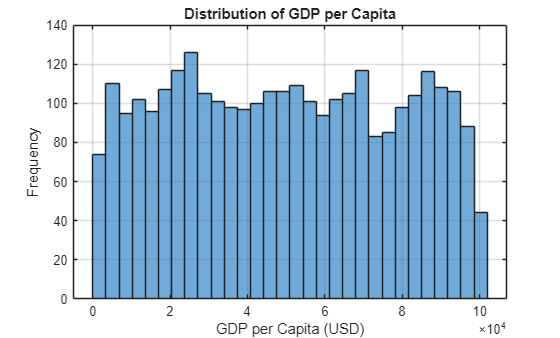

histogram(wpmain.GDPPerCapita_USD_, 30)
xlabel("GDP per Capita (USD)")
ylabel("Frequency")
title("Distribution of GDP per Capita")
grid on
saveas(gcf,'GDP HISTOGRAM.png')

## Pareto Chart of Population Density by Country

### Summarizing data by Country and Including mean Population Density

cT= groupsummary(wpmain,"Country","mean","PopulationDensity_peoplePerKm__");

### Pareto Chart Plot

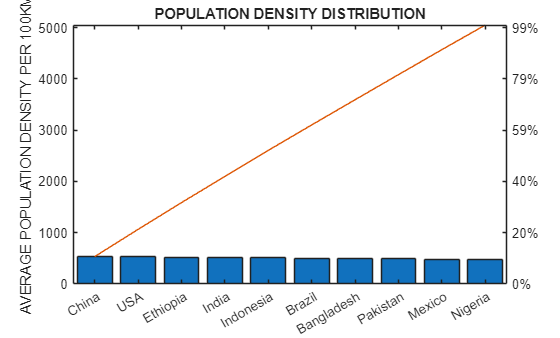

pareto(cT.mean_PopulationDensity_peoplePerKm__,cT.Country)
ylabel("AVERAGE POPULATION DENSITY PER 100KM")
title("POPULATION DENSITY DISTRIBUTION")
saveas(gcf,'Population Distribution PARETO CHART.png')

## Relationship between Contaminant Levels and GDP per Capita

### Logarithmic Plot  

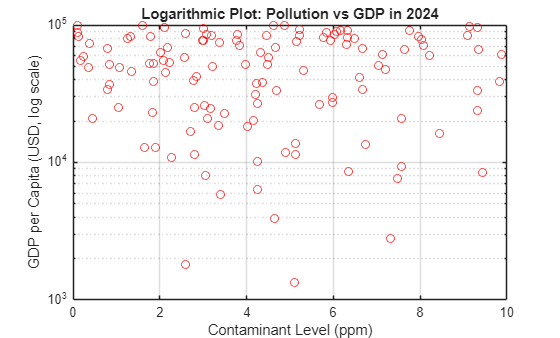

semilogy(wp_2024.ContaminantLevel_ppm_,wp_2024.GDPPerCapita_USD_,'r O')
xlabel("Contaminant Level (ppm)")
ylabel("GDP per Capita (USD, log scale)")
title("Logarithmic Plot: Pollution vs GDP in 2024")
grid on
saveas(gcf,'Contamination against GDP LOGARITHMIC PLOT.png')

## Distribution of Diarrheal Cases by Year & Region

### Summarizing data by year and region showing mean diarrheal cases.

regionYearSummary2 = groupsummary(wpmain,["Year","Region"],"mean","DiarrhealCasesPer100_000People");

This line of code was used to delete the groupcount coloumn.

regionYearSummary2.GroupCount = [];

We used "unstack", to convert the region column to a row.

regionYearSummary3 = unstack(regionYearSummary2, 'mean_DiarrhealCasesPer100_000People','Region');

### Convert the table into  numerical array form

t1 = table2array(regionYearSummary3(:, 2:end));

### 3D Bar plot

figure(Position=[100,100,1200,650])
bar3(t1)
legend(regionYearSummary2.Region)

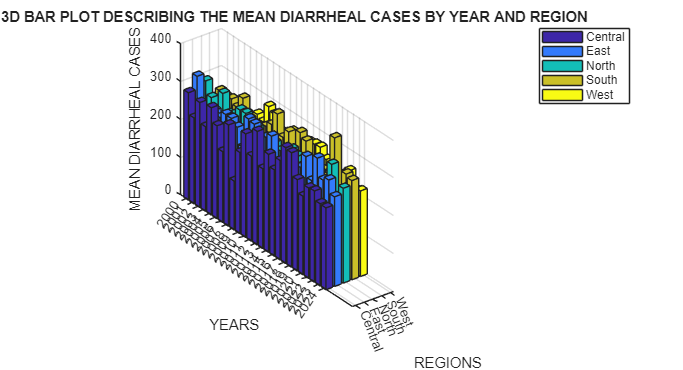

xlabel("REGIONS")
xticklabels(regionYearSummary2.Region)
ylabel("YEARS")
yticklabels(regionYearSummary3.Year)
yticks(1:25)
zlabel("MEAN DIARRHEAL CASES")
title('A 3D BAR PLOT DESCRIBING THE MEAN DIARRHEAL CASES BY YEAR AND REGION')
saveas(gcf,"MEAN DIARRHEAL CASES BY YEAR AND REGION 3D BAR PLOT.png")

### 3D Surface Plot

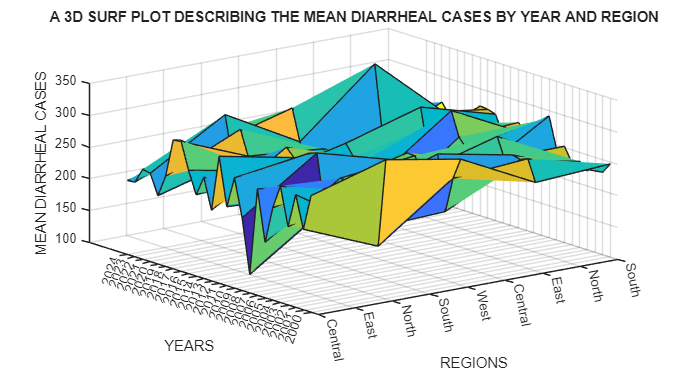

figure(Position=[50,50,1200,650])
surf(t1)
xlabel("REGIONS")
xticklabels(regionYearSummary2.Region)
ylabel("YEARS")
yticklabels(regionYearSummary3.Year)
yticks(1:25)
zlabel("MEAN DIARRHEAL CASES")
title('A 3D SURF PLOT DESCRIBING THE MEAN DIARRHEAL CASES BY YEAR AND REGION')
saveas(gcf,"MEAN DIARRHEAL CASES BY YEAR AND REGION 3D SURF PLOT.png")